%% Preparación del entorno
clear;
clc;
close all;

%% Definición simbólica del sistema
syms p53 Stat3 Np63 Pstat3
assume(Pstat3 >= 0)

% Parámetros
Pp53 = 1.1380;
N = 0.6184;
k = 1.8558;
B = 1.6019;
ANp63p53 = 1.3864;
C1 = 0.8905;
dNp63p53 = 1.0944;
Dp53 = 0.1597;
ANp63s = 0.0053;
Ap53s = 1.1090;
Dstat3 = 0.8895;
PNp63 = 5.7201;
Astat3Np = 0.9350;
C2 = 1.2659;
dp53NP = 0.0000;
C3 = 2.8150;
dNp63Np63 = 0.2113;
DNp63 = 3.3663;

% Ecuaciones del sistema
f1 = (Pp53 + B*(p53^N)/(k^N + p53^N) + ANp63p53*Np63) * C1/(1 + dNp63p53*Np63) - Dp53*p53;
f2 = (Pstat3 + ANp63s*Np63 + Ap53s*p53) - Dstat3*Stat3;
f3 = (PNp63 + Astat3Np*Stat3) * C2/(1 + dp53NP*p53) * C3/(1 + dNp63Np63*Np63) - DNp63*Np63;

bifurcacion = []; % Para almacenar [Pstat3, p53, Stat3, Np63, estabilidad]

% Variables simbólicas a resolver
vars = [p53, Stat3, Np63];

% Preparar vector de valores para Pstat3
Pstat3_vals = linspace(0, 50, 200);
resultados = [];

for i = 1:length(Pstat3_vals)
    valor_P = Pstat3_vals(i);
    soluciones = vpasolve([subs(f1, Pstat3, valor_P)==0, ...
                           subs(f2, Pstat3, valor_P)==0, ...
                           subs(f3, Pstat3, valor_P)==0], ...
                          [p53, Stat3, Np63]);
    
    % Convertir soluciones a vectores numéricos (puede haber varias)
    p53_sol = double(soluciones.p53);
    Stat3_sol = double(soluciones.Stat3);
    Np63_sol = double(soluciones.Np63);
    
    for j = 1:length(p53_sol)
        x1 = p53_sol(j);
        x2 = Stat3_sol(j);
        x3 = Np63_sol(j);

        % Verificar si el punto es real y no negativo
        if all(isreal([x1 x2 x3])) && all([x1 x2 x3] >= 0)
            % Construir la matriz Jacobiana en el punto
            J = jacobian([f1, f2, f3], [p53, Stat3, Np63]);
            J_num = double(subs(J, [p53, Stat3, Np63, Pstat3], [x1, x2, x3, valor_P]));
            autovalores = eig(J_num);
            
            % Clasificación básica de estabilidad
            if all(real(autovalores) < 0)
                tipo = "Estable";
            elseif any(real(autovalores) > 0) && any(real(autovalores) < 0)
                tipo = "Silla";
            else
                tipo = "Inestable";
            end
            
            % Guardar resultado
            resultados = [resultados; {valor_P, x1, x2, x3, tipo}];
        end
    end
end

% Convertir resultados a tabla
bifurcacion_tbl = cell2table(resultados, 'VariableNames', ...
    {'Pstat3', 'p53', 'Stat3', 'Np63', 'Estabilidad'});

% Mostrar una parte de la tabla
disp(head(bifurcacion_tbl, 10))

    Pstat3      p53      Stat3      Np63     Estabilidad
    _______    ______    ______    ______    ___________

          0    7.7487       9.7    6.5608     "Estable" 
    0.25126    7.7421    9.9746    6.6326     "Estable" 
    0.50251    7.7356    10.249    6.7038     "Estable" 
    0.75377    7.7293    10.524    6.7745     "Estable" 
      1.005    7.7232      10.8    6.8448     "Estable" 
     1.2563    7.7172    11.075    6.9146     "Estable" 
     1.5075    7.7114    11.351    6.9839     "Estable" 
     1.7588    7.7057    11.627    7.0527     "Estable" 
     2.0101    7.7002    11.902    7.1211     "Estable" 
     2.2613    7.6947    12.179     7.189     "Estable" 



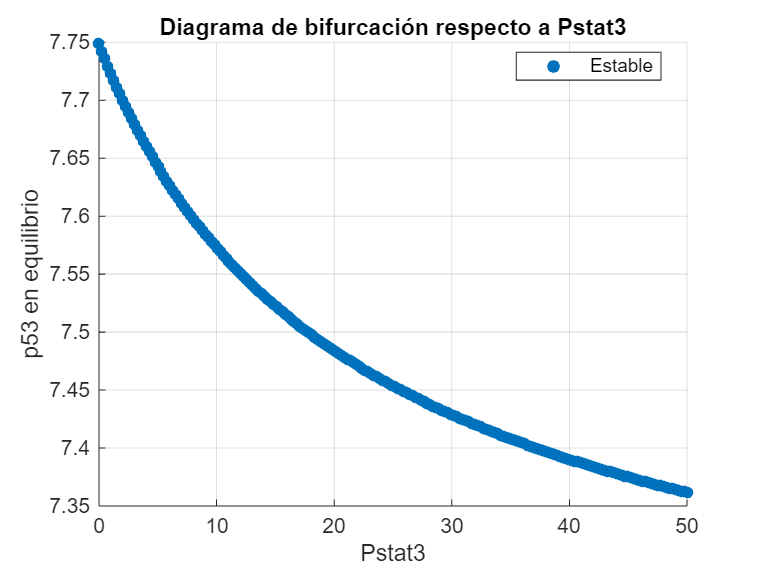


% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.Pstat3(idx), bifurcacion_tbl.p53(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('Pstat3'); ylabel('p53 en equilibrio');
title('Diagrama de bifurcación respecto a Pstat3');
legend('Location', 'best');
grid on;

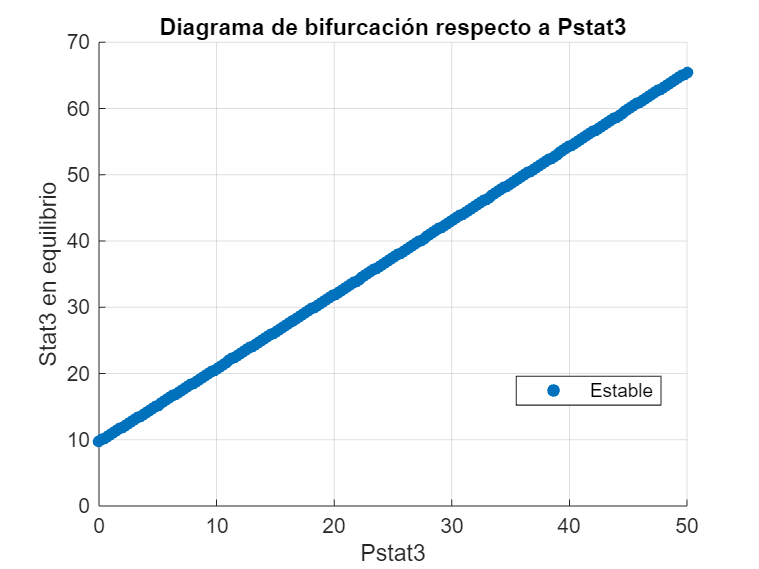



% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.Pstat3(idx), bifurcacion_tbl.Stat3(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('Pstat3'); ylabel('Stat3 en equilibrio');
title('Diagrama de bifurcación respecto a Pstat3');
legend('Location', 'best');
grid on;

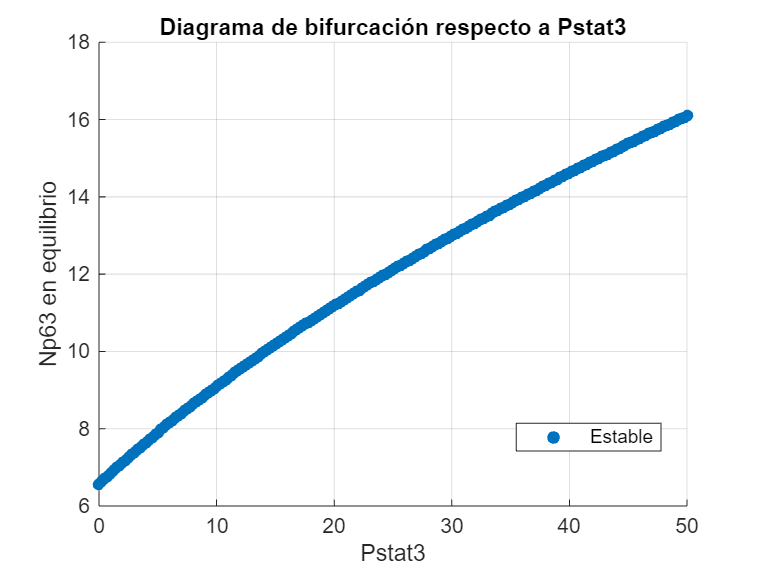


% Gráfico bifurcación
figure;
hold on;
tipos = unique(bifurcacion_tbl.Estabilidad);
colores = lines(length(tipos));

for i = 1:length(tipos)
    tipo_actual = tipos(i);
    idx = bifurcacion_tbl.Estabilidad == tipo_actual;
    scatter(bifurcacion_tbl.Pstat3(idx), bifurcacion_tbl.Np63(idx), 30, ...
        'filled', 'DisplayName', tipo_actual, 'MarkerFaceColor', colores(i,:));
end

xlabel('Pstat3'); ylabel('Np63 en equilibrio');
title('Diagrama de bifurcación respecto a Pstat3');
legend('Location', 'best');
grid on;